# **Motion Planning with RRT for Fixed-Wing UAV **

This example demonstrates motion planning of a fixed-wing unmanned aerial vehicle (UAV) using the rapidly exploring random tree (RRT) algorithm given a start and goal pose on a 3-D map. A fixed-wing UAV is nonholonomic in nature, and must obey aerodynamic constraints like maximum roll angle, flight path angle, and airspeed when moving between waypoints.

In this example you will set up a 3-D map, provide the start pose and goal pose, plan a path with RRT using 3-D Dubins motion primitives, smooth the obtained path, and simulate the flight of the UAV.

% Set RNG seed for repeatable result
rng(1,"twister");

### Load Map

Load the 3-D occupancy map `uavMapCityBlock.mat`, which contains a set of pregenerated obstacles, into the workspace. The occupancy map is in an ENU (East-North-Up) frame.

mapData = load("uavMapCityBlock.mat","omap");
omap = mapData.omap;
% Consider unknown spaces to be unoccupied
omap.FreeThreshold = omap.OccupiedThreshold;

Using the map for reference, select an unoccupied start pose and goal pose.

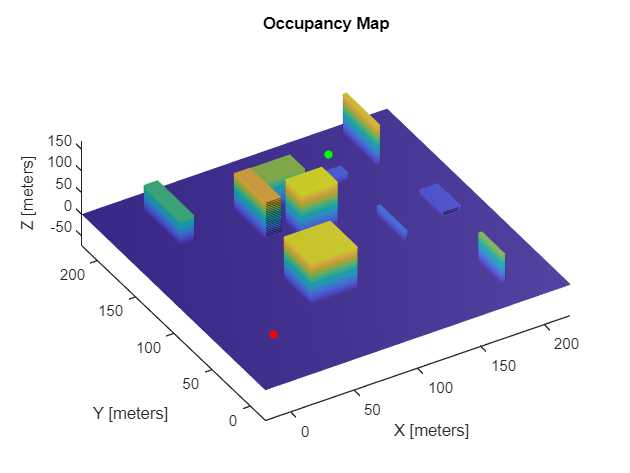

startPose = [12 22 25 pi/2];
goalPose = [150 180 35 pi/2];
figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
hold off
view([-31 63])

### Plan a Path with RRT Using 3-D Dubins Motion Primitives

RRT is a tree-based motion planner that builds a search tree incrementally from random samples of a given state space. The tree eventually spans the search space and connects the start state and the goal state. Connect the two states using a [`uavDubinsConnection`](docid:uav_ref#object_uavdubinsconnection) object that satisfies aerodynamic constraints. Use the `validatorOccupancyMap3D` object for collision checking between the fixed-wing UAV and the environment.

#### Define the State Space Object

This example provides a predefined state space, `ExampleHelperUavStateSpace`, for path planning. The state space is defined as `[x y z headingAngle]`, where `[x y z]` specifies the position of the UAV and `headingAngle` specifies the heading angle in radians. The example uses a [uavDubinsConnection](docid:uav_ref#object_uavdubinsconnection) object as the kinematic model for the UAV, which is constrained by maximum roll angle, airspeed, and flight path angle. Create the state space object by specifying the maximum roll angle, airspeed, and flight path angle limits properties of the UAV as name-value pairs. Use the `"Bounds"` name-value pair argument to specify the position and orientation boundaries of the UAV as a 4-by-2 matrix, where the first three rows represent the `x`-, `y`-, and `z`-axis boundaries inside the 3-D occupancy map and the last row represents the heading angle in the range `[-pi, pi]` radians.

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[-20 220; -20 220; 10 100; -pi pi]);

'ExampleHelperUAVStateSpace' is used in Motion Planning with RRT for
Fixed-Wing UAV.

Set the threshold bounds of the workspace based on the target goal pose. This threshold dictates how large the target workspace goal region around the goal pose is, which is used for bias sampling of the workspace goal region approach.

threshold = [(goalPose-0.5)' (goalPose+0.5)'; -pi pi];

Use the `setWorkspaceGoalRegion` function to update the goal pose and the region around it.

setWorkspaceGoalRegion(ss,goalPose,threshold)

#### Define the State Validator Object

The `validatorOccupancyMap3D` object determines that a state is invalid if the *xyz*-location is occupied on the map. A motion between two states is valid only if all intermediate states are valid, which means the UAV does not pass through any occupied location on the map. Create a `validatorOccupancyMap3D` object by specifying the state space object and the inflated map. Then set the validation distance, in meters, for interpolating between states.

sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.1;

#### Set Up the RRT Path Planner

Create a `plannerRRT` object by specifying the state space and state validator as inputs. Set the `MaxConnectionDistance`, `GoalBias`, and `MaxIterations` properties of the planner object, and then specify a custom goal function. This goal function determines that a path has reached the goal if the Euclidean distance to the target is below a threshold of 5 m.

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 50;
planner.GoalBias = 0.10;  
planner.MaxIterations = 400;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 5);

#### Execute Path Planning

Perform RRT-based path planning in 3-D space. The planner finds a path that is collision-free and suitable for fixed-wing flight.

[pthObj,solnInfo] = plan(planner,startPose,goalPose);

#### Simulate a UAV Following the Planned Path

Visualize the planned path. Interpolate the planned path based on the UAV Dubins connections. Plot the interpolated states as a green line.

Simulate the UAV flight using the provided helper function, `exampleHelperSimulateUAV`, which requires the waypoints, airspeed, and time to reach the goal (based on airspeed and path length). The helper function uses the [`fixedwing`](docid:uav_ref#mw_85ffb974-cf1f-4d6b-86d2-dff353168ec7) guidance model to simulate the UAV behavior based on control inputs generated from the waypoints. Plot the simulated states as a red line.

Notice that the simulated UAV flight deviates slightly from the planned path because of small control tracking errors. Also, the 3-D Dubins path assumes instantaneous changes in the UAV roll angle, but the actual dynamics have a slower response to roll commands. One way to compensate for this lag is to plan paths with more conservative aerodynamic constraints. 

if (solnInfo.IsPathFound)
    figure("Name","OriginalPath")
    % Visualize the 3-D map
    show(omap)
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"red","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
    
    interpolatedPathObj = copy(pthObj);
    interpolate(interpolatedPathObj,1000)
    
    % Plot the interpolated path based on UAV Dubins connections
    hReference = plot3(interpolatedPathObj.States(:,1), ...
        interpolatedPathObj.States(:,2), ...
        interpolatedPathObj.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    % Plot simulated UAV trajectory based on fixed-wing guidance model
    % Compute total time of flight and add a buffer
    timeToReachGoal = 1.05*pathLength(pthObj)/ss.AirSpeed;
    waypoints = interpolatedPathObj.States;
    [xENU,yENU,zENU] = exampleHelperSimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    legend([hReference,hSimulated],"Reference","Simulated","Location","best")
    hold off
    view([-31 63])
end

### Smooth Dubins Path and Simulate UAV Trajectory

The original planned path makes some unnecessary turns while navigating towards the goal. Simplify the 3-D Dubins path by using the path smoothing algorithm provided with the example, `exampleHelperUAVPathSmoothing`. This function removes intermediate 3-D Dubins poses based on an iterative strategy. For more information on the smoothing strategy, see [1]. The smoothing function connects non-sequential 3-D Dubins poses with each other as long as doing so does not result in a collision. The smooth paths generated by this process improve tracking characteristics for the fixed-wing simulation model. Simulate the fixed-wing UAV model with these new, smoothed waypoints.

if (solnInfo.IsPathFound)
    smoothWaypointsObj = exampleHelperUAVPathSmoothing(ss,sv,pthObj);
    
    figure("Name","SmoothedPath")
    % Plot the 3-D map
    show(omap)
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"red","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
    
    interpolatedSmoothWaypoints = copy(smoothWaypointsObj);
    interpolate(interpolatedSmoothWaypoints,1000)
    
    % Plot smoothed path based on UAV Dubins connections
    hReference = plot3(interpolatedSmoothWaypoints.States(:,1), ...
        interpolatedSmoothWaypoints.States(:,2), ...
        interpolatedSmoothWaypoints.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    % Plot simulated flight path based on fixed-wing guidance model
    waypoints = interpolatedSmoothWaypoints.States;
    timeToReachGoal = 1.05*pathLength(smoothWaypointsObj)/ss.AirSpeed;
    [xENU,yENU,zENU] = exampleHelperSimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    
    legend([hReference,hSimulated],"SmoothedReference","Simulated","Location","best")
    hold off
    view([-31 63]);
end

The smoothed path is much shorter and shows improved tracking overall.

## References

[1] Beard, Randal W., and Timothy W. McLain. *Small Unmanned Aircraft: Theory and Practice*. Princeton, N.J: Princeton University Press, 2012.

[2] Hornung, Armin, Kai M. Wurm, Maren Bennewitz, Cyrill Stachniss, and  Wolfram Burgard. “OctoMap: An Efficient Probabilistic 3D Mapping  Framework Based on Octrees.” *Autonomous Robots* 34, no. 3 (April 2013): 189–206. [https://doi.org/10.1007/s10514-012-9321-0](https://doi.org/10.1007/s10514-012-9321-0).

*Copyright 2020 The MathWorks, Inc.*